# Classify ECG Signals Using LSTMs

ECGs records the electrical activity of a person's heart over time. Physicians use ECGs to visually detect whether a patient's heartbeat is normal or irregular.

We will be creating an LSTM Network to determine the presence of an irregular heartbeat called Atrial Fibrilation (AFib). This occurs when the heart's upper chambers beat out of coordination with the heart's lower chambers.

The original ECG data comes from the PhysioNet 2017 Challenge, which is available at [https://physionet.org/challenge/2017/.](https://physionet.org/challenge/2017/.)

This demo is structured according to the four phases of the typical machine learning workflow:

- Access and Explore Data

- Preprocess Data

- Develop Predictive Models

- Integrate Models with Systems

clear

## 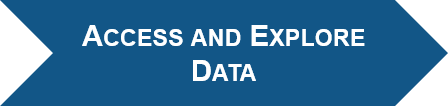

## Load and Visualize Data

The data for this example consists of a set of ECG signals sampled at 300 Hz and divided into 2 classes:

- N = Normal (5050 signals)

- A = AFib (738 signals)

load PhysionetData.mat

This adds two variables to our workspace:

- `Signals` - cell array that holds ECG Signals

- `Labels` - categorical array that holds corresponding ground-truth labels

View the first 5 entries of the individual data sets.

Signals(1:5)
Labels(1:5)
summary(Labels)

Most of the ECG signals are 9000 samples long, but there is some variability. Let's create a histogram that shows the length of the signals.

plotSignalLengths(Signals)

Visualize a segment of one signal from each class. Below are two common characteristics of AFib signals:

- Spaced out at irregular intervals.

- Lack a P wave, which pulses before the QRS complex in normal heartbeat.

visualizeECGSignals(Signals)

## 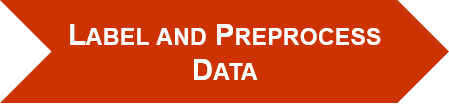

## Prepare Data for Deep Learning

### Standardize the data

Since the ECG Signals are different lengths, we need to first pad and truncate them so they are all 9000 samples long. 

The function segmentSignals ignores signals with fewer than 9000 samples. If the signal over 9000 samples, segmentSignals breaks it into as many 9000-sample segments as possible and ignores the remaining samples.

For example, a signal with 18500 samples becomes two 9000-sample signals and the remaining 500 samples are ignored.

[Signals,Labels] = segmentSignals(Signals,Labels);

### Extract features to improve the performance

Feature extraction from the data can help improve the training and testing accuracies of the classifier. To decide which features to extract, this example follows an approach that computes time-frequency (TF) moments. Each moment can be used as a one-dimensional feature to input to the LSTM. 

We will explore the following TF moments:

- Instantaneous frequency (`instfreq`)

- Spectral entropy (`pentropy`)

**Instantaneous Frequency**

The `instfreq` function estimates the time-dependent frequency of a signal as the first moment of the power spectrogram. The function computes a spectrogram using short-time Fourier transforms over time windows. In this example, `instfreq`, uses a buffer length, n, to compute the spectrogram, whcih results in 255 time windows for a signal of 9000 samples. The 255-long time outputs of the function correspond to the center of the time windows.

Visualize the instantaneous frequency for each type of signal.

fs = 300;
normal = Signals{1};
aFib = Signals{4};

[instFreqN,tN] = instfreq(normal,fs);
[instFreqA,tA] = instfreq(aFib,fs);

plotInstFreq(tN,instFreqN,tA,instFreqA)

**Spectral Entropy**

The spectral entropy measures how spiky/flat the spectrum of a signal is. A signal with a spiky spectrum, like a sum of sinusoids, has low spectral entropy. A signal with a flat spectrum, like white noise, has high spectral entropy. The `pentropy` function estimates the spectral entropy based on a power spectrogram. As with the instantaneous frequency estimation case, `pentropy` uses a buffer length, n, to compute the spectrogram which results in 255 time windows for a signal of 9000 samples. The 255-long time outputs of the function correspond to the center of the time windows.

Visualize the spectral entropy for each type of signal.

[pentropyA,tA2] = pentropy(aFib,fs);
[pentropyN,tN2] = pentropy(normal,fs);

plotPentropy(tN2,pentropyN,tA2,pentropyA);

Use `cellfun` to apply the `instfreq `and` pentropy` function to every cell.

!!! This operation migh take a couple of minutes to perform, hence you can set `calculateFeatures` to `false` and load the variables.

calculateFeatures = false;

if calculateFeatures==true
    instfreqSig = cellfun(@(x)instfreq(x,fs)',Signals,'UniformOutput',false);
    pentropySig = cellfun(@(x)pentropy(x,fs)',Signals,'UniformOutput',false);
    Signals2 = cellfun(@(x,y)[x;y],instfreqSig,pentropySig,'UniformOutput',false);
else
    load ExtractedFeatures.mat
end

Signals2(1:5)

### Splitting Dataset into Training and Test Sets

Partition the dataset so that 90% of the signals are used for training our network and 10% are used to test our network.

Split the signals according to classes:

afibX = Signals2(Labels=='A');
afibY = Labels(Labels=='A');

normalX = Signals2(Labels=='N');
normalY = Labels(Labels=='N');

Use `dividerand` to divide targets from each class randomly into training and testing sets.

[trainIndA,~,testIndA] = dividerand(718,0.9,0.0,0.1);
[trainIndN,~,testIndN] = dividerand(4937,0.9,0.0,0.1);

XTrainA = afibX(trainIndA);
YTrainA = afibY(trainIndA);

XTrainN = normalX(trainIndN);
YTrainN = normalY(trainIndN);

XTestA = afibX(testIndA);
YTestA = afibY(testIndA);

XTestN = normalX(testIndN);
YTestN = normalY(testIndN);

### Handling Data Imbalance with Oversampling

Since over 80% of the signals are *Normal*, the classifier would learn that it can achieve a high accuracy by classifying all the signals as *Normal*. 

To avoid this bias, we duplicate the *AFib* signals until we have an equal number of *Normal* and *AFib* signals. This duplication is called oversampling, and it is one form of data augmentation used in deep learning.

- Training - Use first 4438 *Normal* signals and use `repmat` to repeat the first 634 *AFib* signals

- Test - Use first 490 *Normal* signals, and use `repmat` to repeat the first 70 *AFib* signals

XTrain = [repmat(XTrainA(1:634),7,1); XTrainN(1:4438)];
YTrain = [repmat(YTrainA(1:634),7,1); YTrainN(1:4438)];

XTest = [repmat(XTestA(1:70),7,1); XTestN(1:490)];
YTest = [repmat(YTestA(1:70),7,1); YTestN(1:490);];

The distribution between *Normal* and *AFib* signals is now evenly balanced.

summary(YTrain)
summary(YTest)

## Standardize the Data

The instantaneous frequency and the spectral entropy have very different means which could impact training time and accuracy. 

One common practice is standardizing our dataset using the mean and standard deviation from the training and test sets (z-scoring). 

[XTrainSD,XTestSD] = standardizeData(XTrain,XTest);

## 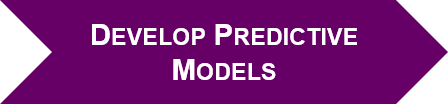

## Define LSTM Architecture

LSTM networks can learn long-term dependencies between time steps of sequence data. This example uses the bidirectional LSTM layer `bilstmLayer`, as it looks at the sequence in both forward and backward directions.

Since we extracted two features, our signal has two dimensions. Specify a bidirectional LSTM layer with an output size of 100 and output the last element of the sequence. This command instructs the bidirectional LSTM layer to map the input time series into 100 features and then prepares the output for the fully connected layer. Finally, specify two classes by including a fully connected layer of size 2, followed by a softmax layer and a classification layer. 

There are three steps to preparing a deep neural network for training in MATLAB:

- Design your network architecture

- Specify the data to use for training

- Adjust your [`trainingOptions`](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) (hyperparameters)

### **Create LSTM network**

**The Deep Network Designer (DND) provides a graphical interface for doing all three steps.**

You can design your network using the Deep Network Designer App. To open it, on the **Apps** tab, under **Machine Learning and Deep Learning**, click the app icon. Alternatively, you can open the app from the command line [`deepNetworkDesigner`](https://uk.mathworks.com/help/deeplearning/ug/build-networks-with-deep-network-designer.html).

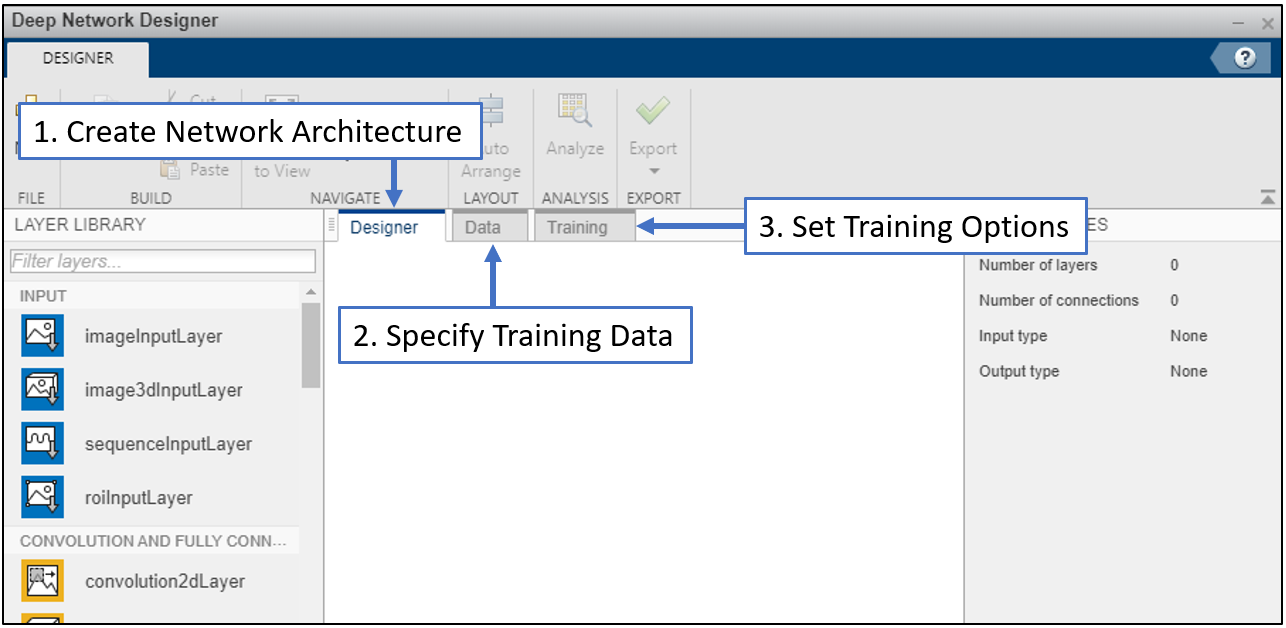

**Step 1: Choose network architecture**

On opening the DND, chose `Blank Network`. 

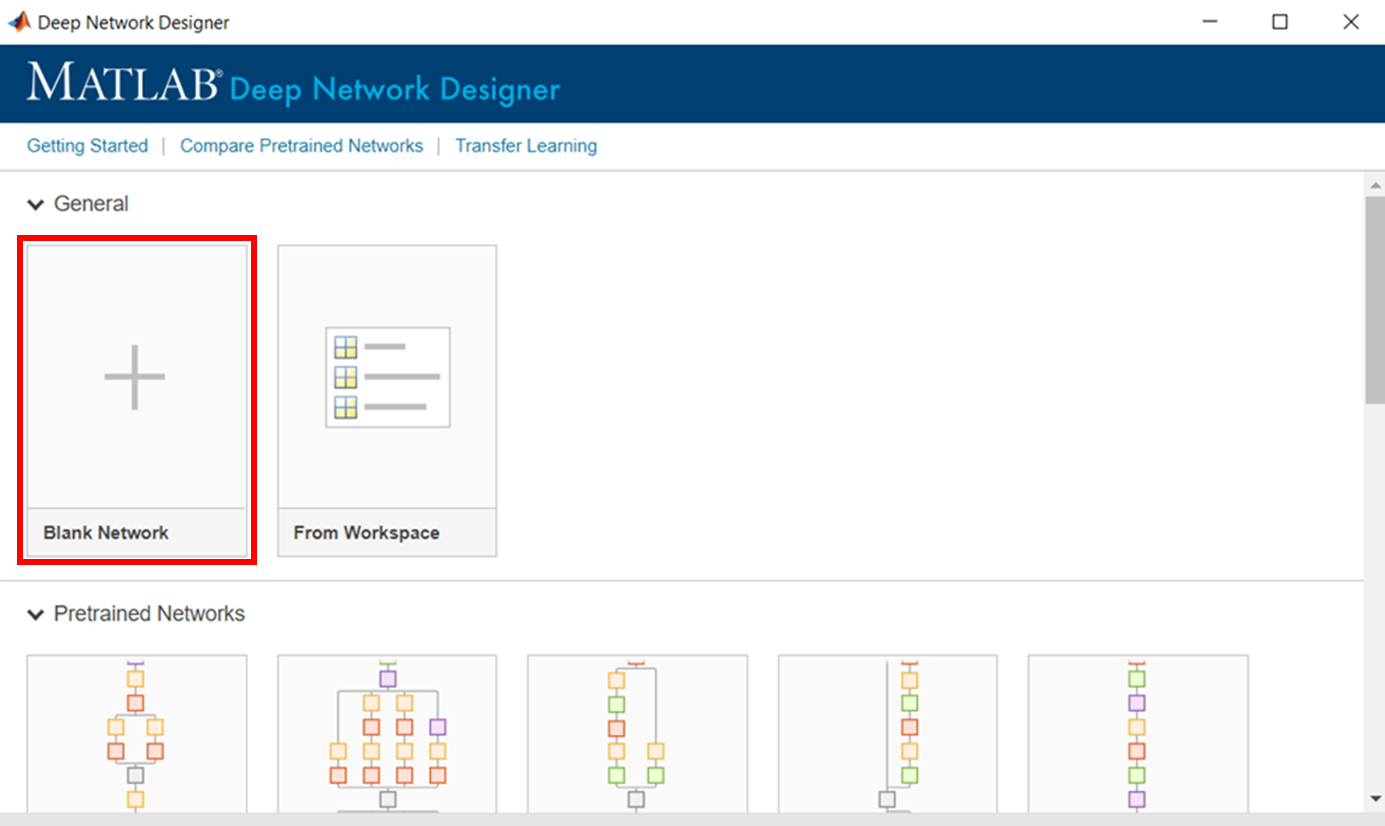

**Step 2: Design network architecture **

Using the `Designer` tab, create the architecture below by dragging and dropping required layers and setting the required values.

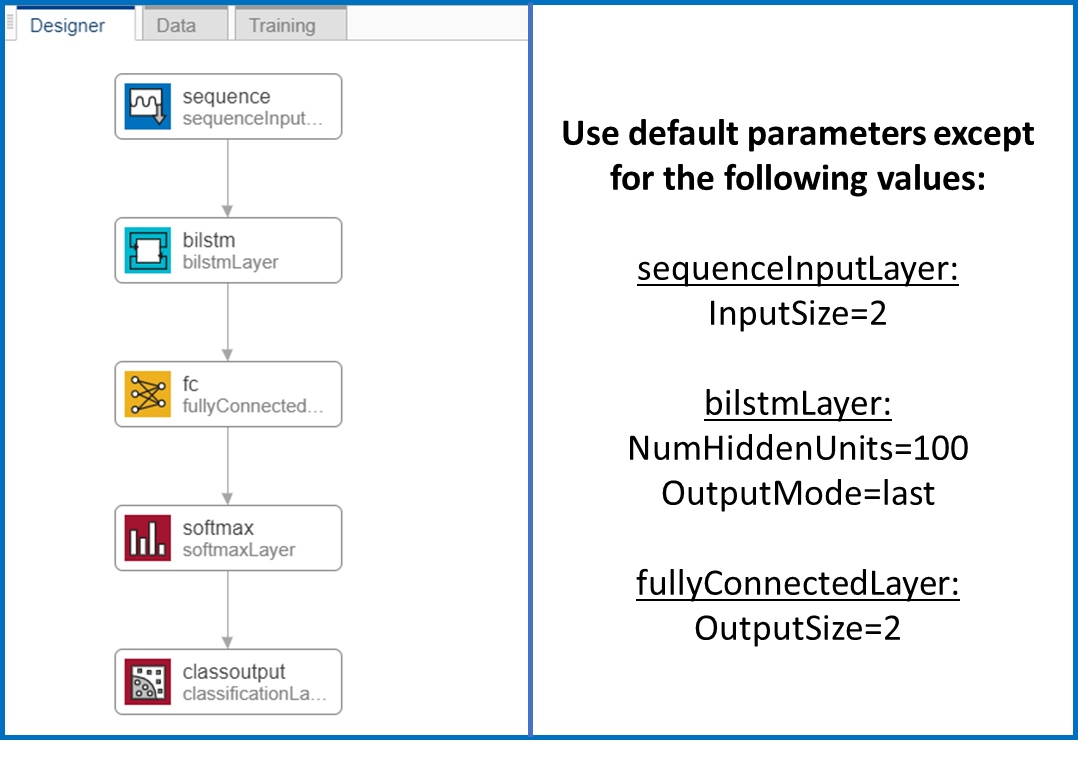

**Step 3: Export network**

Export the network to workspace and call it` layers` or generate code.

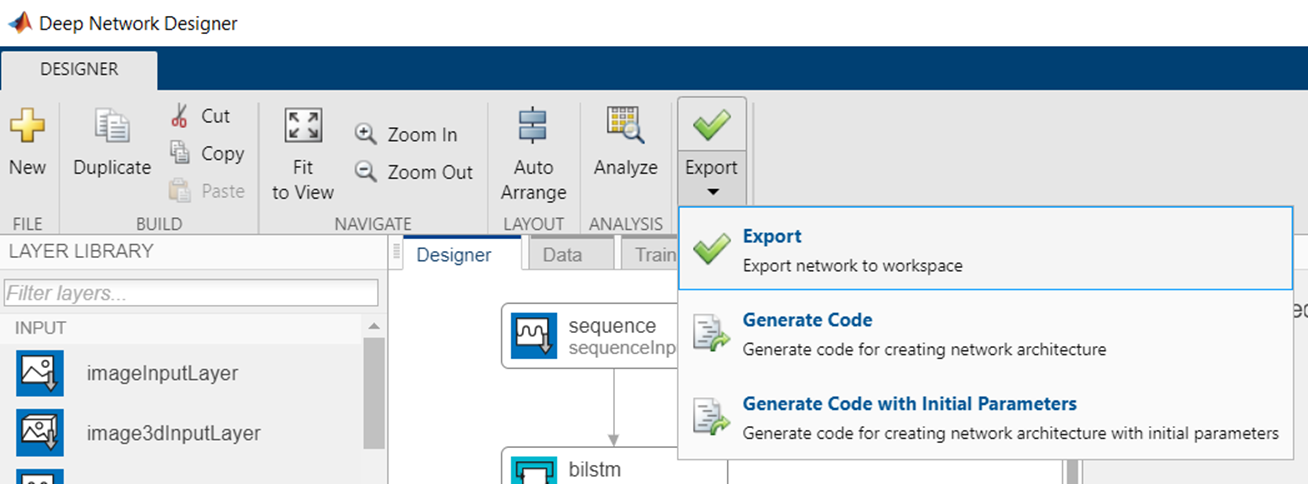

Alternatively you can design the network programmatically. To do so, simply uncomment the next code section.

% layers = [ ...
%     sequenceInputLayer(2)
%     bilstmLayer(100,'OutputMode','last')
%     fullyConnectedLayer(2)
%     softmaxLayer
%     classificationLayer
%     ];


### Set training options

Specify the training options. Set the maximum number of epochs to 30 to allow the network to make 30 passes through the training data.

options = trainingOptions('adam', ...
    'MaxEpochs',30, ...
    'MiniBatchSize', 150, ...
    'InitialLearnRate', 0.01, ...
    'SequenceLength', 1000, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment',"auto",...
    'plots','training-progress', ...
    'Verbose',false);

## Train the Network

Training the network will require a GPU. If you'd like to save time, load the pretrained network by setting `doTrain` to `false`.

doTrain = false;

if doTrain==true
    net2 = trainNetwork(XTrainSD,YTrain,layers,options);
else
    load ECGNetwork.mat
end


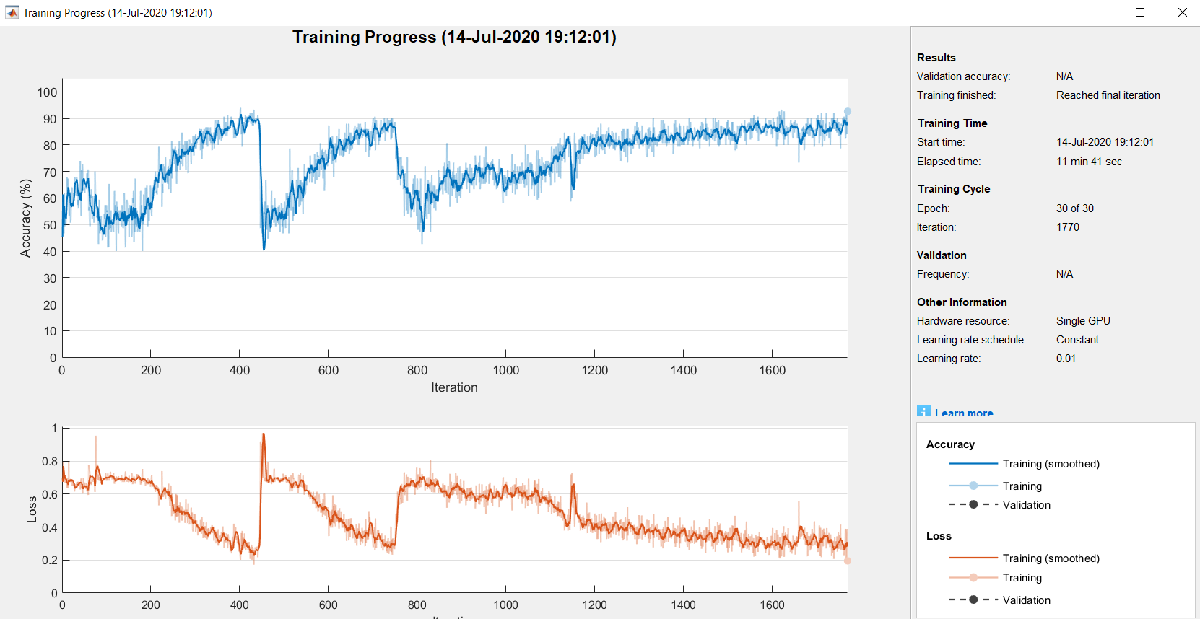

The top subplot of the training-progress plot represents the training accuracy, which is the classification accuracy on each mini-batch. This value should ideally approach 100%. The bottom subplot displays the training loss, which is the cross-entropy loss on each mini-batch. When training progresses successfully, this value typically decreases towards zero.

## View the results and assess the accuracy

Let's test our model on the test data. 

testPred = classify(net2,XTestSD,'SequenceLength',1000);

Calculate the testing accuracy and visualize the classification performance as a confusion matrix.

LSTMAccuracy = sum(testPred == YTest)/numel(YTest)*100
figure
ccLSTM = confusionchart(YTest,testPred);
ccLSTM.Title = 'Confusion Chart for LSTM';
ccLSTM.ColumnSummary = 'column-normalized';
ccLSTM.RowSummary = 'row-normalized';

Tips to improve the network perfomanace:

- optimize hyperparameters

- modify the network architecture

- add validation data set

- ...

## TO DO:

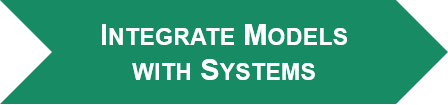

You can now deploy your network.

## Key Takeaways

- LSTM networks are one approach for signal classification

- Oversampling used to avoid classification bias with imbalanced datasets

- LSTMs may not perform well on raw signal.

- Feature extraction prior to training can improve accuracy of LSTM

*Copyright 2020 The MathWorks, Inc.*